x = [0,1,2];
y = [1,0,1];
path = Path(x,y,0.25);
len = path.getLength()

len = 2.7342

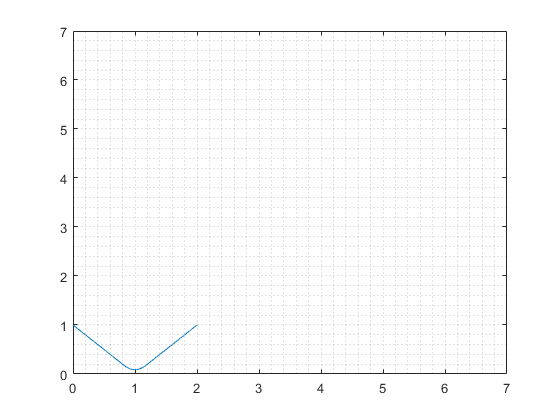

s = [0:.001:len];
[x1,y1] = path.getPoint(s);
figure();
plot(x1,y1)
xlim([0,7])
ylim([0,7])
grid minor

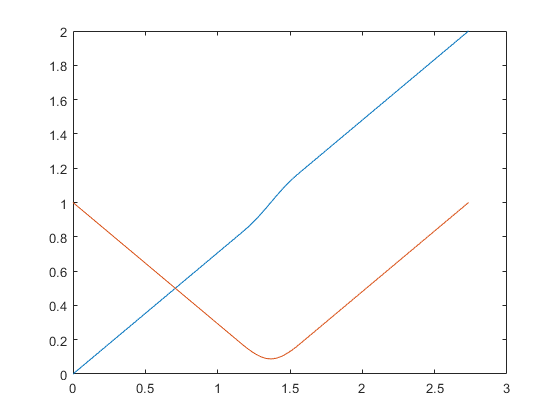


figure()
plot(s,x1)
hold on;
plot(s,y1)

[xt,yt] = path.diff(s)

xt =     0.7071
    0.7071
    0.7071
    0.7071
    0.7071
    0.7071
    0.7071
    0.7071
    0.7071
    0.7071


yt =    -0.7071
   -0.7071
   -0.7071
   -0.7071
   -0.7071
   -0.7071
   -0.7071
   -0.7071
   -0.7071
   -0.7071


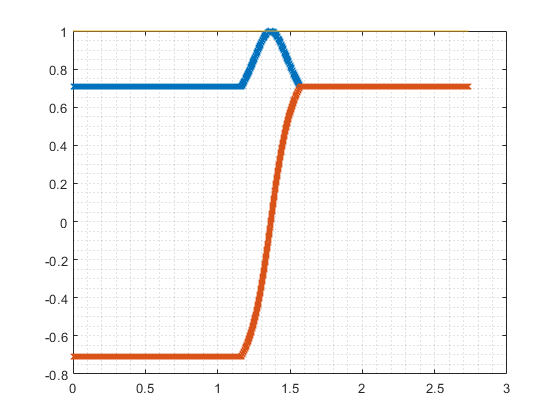


figure();
plot(s,xt,":x");
hold on
plot(s,yt,":x")
plot(s,sqrt(xt.^2+yt.^2))
grid minor

b = BezierCurve([0,1,2], [0,0,1], 0.5)
dt = 0.01
s = [0:0.01:b.length]
[x,y] = b.getPoint(s)
figure();
%plot([0,1,2], [0,0,1], "x")
hold on
plot(x,y,":x")
figure();
plot(s,x)

ax = (b.startPoint.x - 2*b.controlPoint.x + b.endPoint.x);
ay = (b.startPoint.y - 2*b.controlPoint.y + b.endPoint.y);
bx = (2*b.controlPoint.x - 2*b.startPoint.x);
by = (2*b.controlPoint.y - 2*b.startPoint.y);

sIn = @(t)( (t/2 + (4*ax*bx + 4*ay*by)/(4*(4*ax^2 + 4*ay^2)))*(t*(4*ax*bx + 4*ay*by) ...
    + bx^2 + by^2 + t^2*(4*ax^2 + 4*ay^2))^(1/2) ...
   - (log((2*ax*bx + 2*ay*by + t*(4*ax^2 + 4*ay^2))/(4*ax^2 + 4*ay^2)^(1/2) ...
   + (t*(4*ax*bx + 4*ay*by) + bx^2 + by^2 ...
   + t^2*(4*ax^2 + 4*ay^2))^(1/2))*((4*ax*bx + 4*ay*by)^2/4 ...
   - (4*ax^2 + 4*ay^2)*(bx^2 + by^2)))/(2*(4*ax^2 + 4*ay^2)^(3/2)));

s = @(t) (sIn(t)-sIn(0))
ds = @(t) ((4*ax^2*t^2 + 4*ax*bx*t + 4*ay^2*t^2 + 4*ay*by*t + bx^2 + by^2)^(1/2));
s0 = [0:0.01:b.length];
t = zeros(1,length(s0));
for i=1:length(s0)
        t_prev = 2;
        while abs(t(i)-t_prev) > 1e-4
            t_prev = t(i);
            t(i) = t(i) - (s(t(i)) - s0(i)) / ds(t(i));
        end
end

figure();
plot(t(2:length(t)),diff(t)./diff(s0))
hold on
plot(t(2:length(t)),diff(s0)./diff(t))
%plot(s0,t)
